# Eksamen 2012

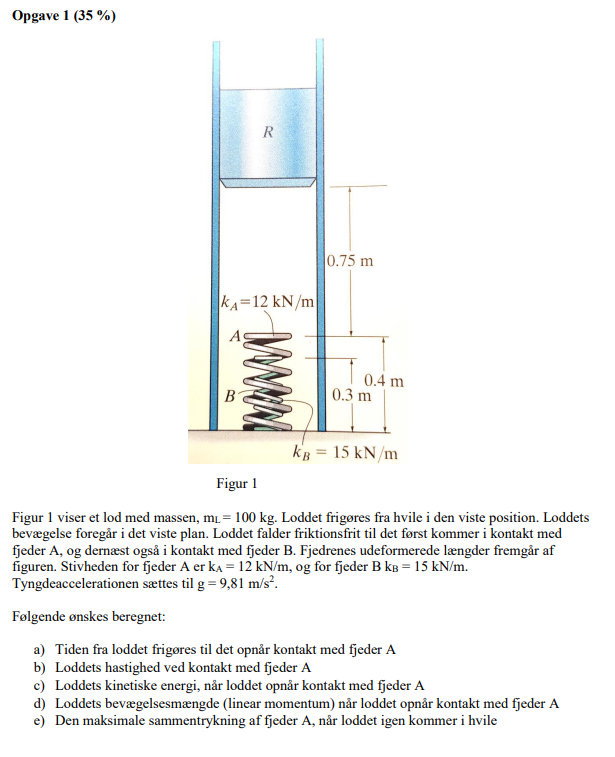

## Opgave a)

clear

g = -9.81;

y0 = 0;
ys = -0.75;
vy0 = 0;

mlod = 100;

syms t
y = 1/2*g*t^2 + vy0*t + y0 == ys;
t = vpa(max(solve(y, t)),4)

$$t = 0.391$$

Tiden er altså 


$$t = 0,391 s$$


## Opgave b)

vy = g*t + vy0;
vy = vpa(vy, 4)

$$vy = -3.836$$

Hastigheden er i nedadgående y-retning


$$v_y = -3.84 \frac{m}{s}$$


## Opgave c)

% Loddets kinetiske energi udregnes
E_kin = 1/2 * mlod * vy^2;
E_kin = vpa(E_kin, 4)

$$E\_kin = 735.7$$


$$E_{kin} = 736N$$


## Opgave d)

% Bevægelsesmængden
P = mlod * abs(vy);
P = vpa(P, 4)

$$P = 383.6$$


$$P = 383,6 kg\cdot \frac{m}{s}$$


## Opgave e)

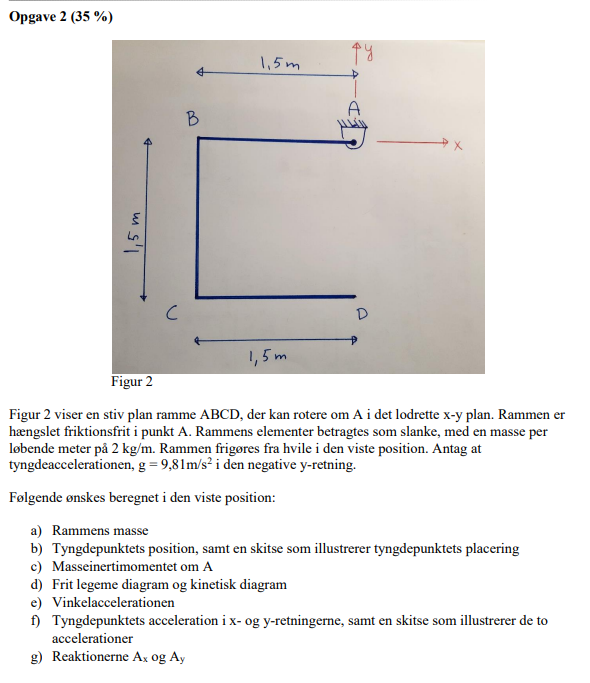

clear

## Opgave a)

l = 1.5; % m
masse = 2; % kg/m

m_arm = l*masse

m_arm = 3


n_arme = 3; % stk



m = m_arm * n_arme

m = 9

Massen for armene bliver


$$m = 9kg$$


## Opgave b)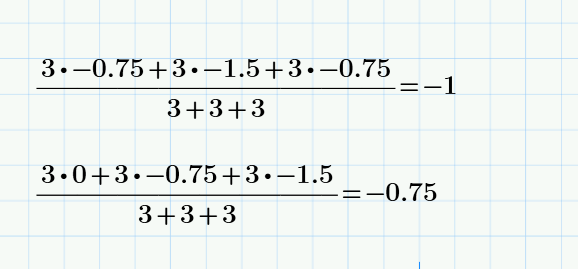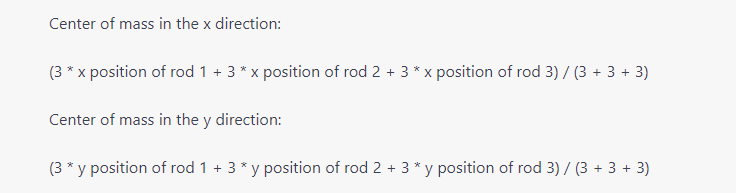

% For hver enkel arm
% arme 1 og 2 og punkt a bærer 1/3 af den lodrette stang, derfor bliver
% deres sammenlagte masser 1/3 større

lx = -l/2;
ly = -l/2;

ltx = -l;
lty = -l;

Tp_x = (m_arm *lx  + m_arm*ltx + m_arm*lx)/(n_arme*m_arm)

Tp_x = -1

Tp_y = (m_arm *0  + m_arm*ly + m_arm*lty)/(n_arme*m_arm)

Tp_y = -0.7500

Tyngdepositionen bliver


$$T_p = -1,0x - 0,75y$$


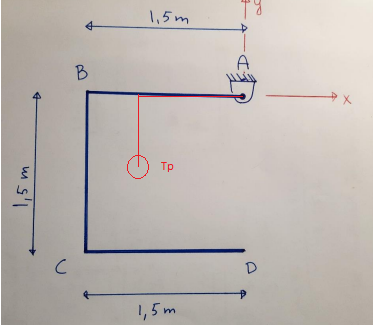

## Opgave c)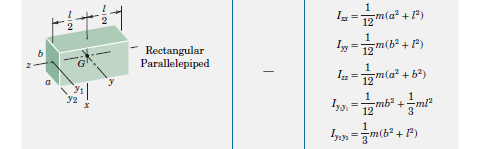

% Masseinertimomentet om punkt A

% Der sker kun rotation om z-aksen

L = 1.5; %længden af hver stang
M = masse * L; % masse af hver stang

% De forskellige stænger giver anledning til momenter, undtagen arm AB, da
% den ligger om rotationsaksen. Tyngdepunktet skal forskydes ind på hver
% stang

Izz1 = 1/3 * M * L^2; % Ligger op ad rotationsaksen

d_BC = L;
Izz2 = 1/3 * M * L^2 + M * d_BC^2;

d_CD = L;
Izz3 = 1/3 * M * L^2+ M * d_CD^2;


Izz_tot = Izz1 + Izz2 + Izz3

Izz_tot = 20.2500


$$I_{zz} = 20,25 kg\cdot m^2$$


## Opgave d)

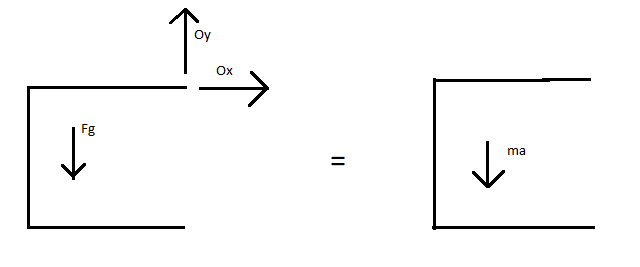

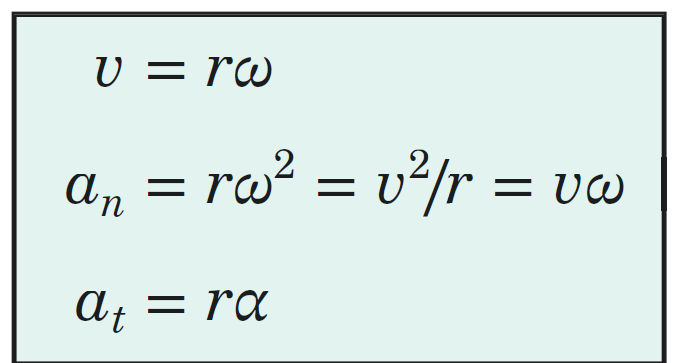

## Opgave e)

% Vi kan finde afstanden og dermed vinklen mellem tyngdepunktet og x-aksen
d_tp = sqrt(Tp_x^2 + Tp_y^2)

d_tp = 1.2500

theta = atand(Tp_y/Tp_x)

theta = 36.8699


g = 9.81;

a_t = g * sind(theta)

a_t = 5.8860


alpha = a_t/d_tp % Forkert

alpha = 4.7088


$$\alpha = 4.71 \frac{rad}{s^2}$$


## Opgave f)

a_t = d_tp * alpha

a_t = 5.8860

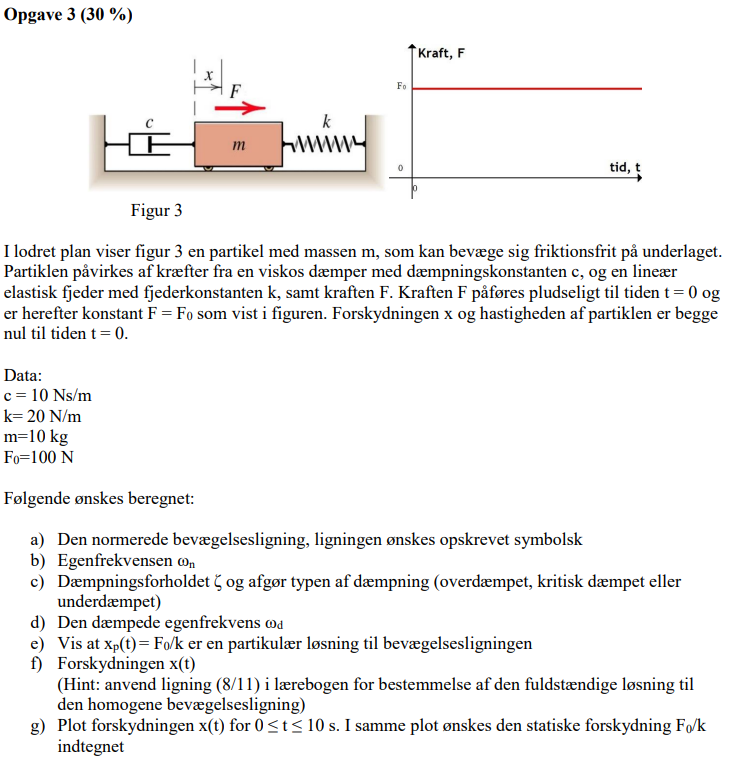

## Opgave a)


$$\ddot x +\omega_n^2x = 0$$



$$\sum F_x = m\cdot\ddot x
\\
F_0 -c \dot x - kx = m\ddot x
\\
\ddot x + \frac{c}{m}\dot x + \frac{k}{m}x = \frac{F_0}{m} 
\\
\ddot x + 2\zeta\omega_n\dot x + \omega_n^2x = \frac{F_0}{m}$$


clear
% Opgave data
c = 10;
k = 20;
m = 10;
F0 = 100;

## Opgave b)

wn = sqrt(k/m)

wn = 1.4142


$$\omega_n = \sqrt{\frac{k}{m}} = 1,414$$


## Opgave c

zeta = c/(2*m*wn)

zeta = 0.3536


$$\zeta = \frac{c}{2m\omega_n} = 0,353$$


Her er der tale om et underdæmpet system

## Opgave d)

wd = wn*sqrt(1 - zeta^2)

wd = 1.3229


$$\omega_d = \omega_n\cdot\sqrt{1 - \zeta^2} = 1,323$$


## Opgave e)

Med bevægelsesligningen fra a), indsættes gættet


$$\ddot x + 2\zeta\omega_n\dot x + \omega_n^2x = \frac{F_0}{m}\\
\\
x_p(t) =  \frac{F_0}{k}
\\
\dot x_p(t) = 0
\\
\ddot x_p(t) = 0
\\
0 + 2\zeta\omega_n\cdot 0 + \omega_n^2\cdot \frac{F_0}{m} = \frac{F_0}{m}
\\
\omega_n = \sqrt{\frac{k}{m}}
\\
 \frac{k}{m}\cdot \frac{F_0}{k} = \frac{F_0}{m}$$


Det ses at den partikulære løsning, løser ligningen

## Opgave f)

clear
% Opgave data
c = 10;
k = 20;
m = 10;
F0 = 100;
t0 = 0; t1 = 10;

syms x1
x0 = F0/k; % N/(N/m) = m
% Formler

wn1 = sqrt(k/m);
zeta1 = c/(2*m*wn1);
wd1 = wn1*sqrt(1 - zeta1^2);

% Diff ligning
syms x(t) zeta lambda t A wn k m C wd psi x

x_plac = C*exp(-zeta*wn*t) * sin(wd*t + psi)  == x0;
% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3);
% til t1;
x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3);

x_vel = diff(x_plac, t) == 0;
% til t0;
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3);
% til t1;
x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3);


eqst0 = [x_vel_numt0, x_plac_numt0];
eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [C, psi];

solt0 = solve(eqst0, unks);

psi = solt0.psi % Den største absolutte værdi skal vælges for psi og C

$$psi = \left(\begin{array}{c} 1.2094292028846515477720268022864\\ -1.9321634507051416906906165809931 \end{array}\right)$$

C = solt0.C   %

$$C = \left(\begin{array}{c} 5.3452248382556340499300035741502\\ -5.3452248382556340499300035741502 \end{array}\right)$$

 
C = vpa(solt0.C(1),4)

$$C = 5.345$$

psi = vpa(solt0.psi(2),4)

$$psi = -1.932$$


x_plac = vpa(C*exp(-zeta1*wn1*t1) * sin(wd1*t1 + psi),3)

$$x\_plac = -0.0344$$

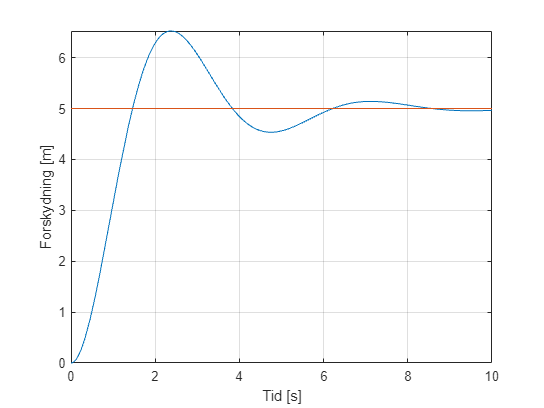

syms func(t)
xp = x0;

func(t) = C*exp(-zeta1*wn1*t) * sin(wd1*t + psi) + xp;

fplot(func(t), [0,10]), xlabel("Tid [s]"), ylabel("Forskydning [m]")
hold on
fplot(xp, [0,10]), grid()
hold off

En anden form af 8.11 er benyttet, hvor C (samling af de "normale" A konstanter), og faseforskydningen $\psi$ er brugt.

Det giver:


$$C = 5,345$$



$$\psi = 1,206$$


Og en forskydning efter 10 sekunder på


$$x(10) = 0,0344m$$



clear
% Opgave data
c = 10;
k = 20;
m = 10;
F0 = 100;
t0 = 0; t1 = 10;

syms x1
x0 = F0/k; % N/(N/m) = m
% Formler

wn1 = sqrt(k/m);
zeta1 = c/(2*m*wn1);
wd1 = wn1*sqrt(1 - zeta1^2);

% Diff ligning
syms x(t) zeta lambda t A wn k m C wd psi x A1 A2

x_plac = (A1*cos(wd*t) + A2*sin(wd*t))*exp(-zeta*wn*t) + x0 == 0

$$x\_plac = {\mathrm{e}}^{-t\,\mathrm{wn}\,\zeta }\,\left(A_{1}\,\cos\left(t\,\mathrm{wd}\right)+A_{2}\,\sin\left(t\,\mathrm{wd}\right)\right)+5=0$$

% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3);
% til t1;
x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3);

x_vel = diff(x_plac, t) == 0;
% til t0;
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3);
% til t1;
x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3);


eqst0 = [x_vel_numt0, x_plac_numt0];
eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [A1, A2];

solt0 = solve(eqst0, unks);
solt1 = solve(eqst1, unks);

A1 = vpa(max(solt0.A1),5)

$$A1 = -5.0$$

A2 = vpa(max(solt0.A2),5)

$$A2 = -1.8898$$


x_plac = vpa((A1*cos(wd1*t1) + A2*sin(wd1*t1))*exp(-zeta1*wn1*t1), 3)

$$x\_plac = -0.0344$$

syms func(t)
xp = x0;

func(t) = (A1*cos(wd1*t) + A2*sin(wd1*t))*exp(-zeta1*wn1*t) + xp;

fplot(func(t), [0,10]), xlabel("Tid [s]"), ylabel("Forskydning [m]")
hold on
fplot(xp, [0,10]), grid()
hold off